# Ampliación de Métodos Numéricos.

# Examen de MATLAB. 

### Apellido: Gil Álamo

### **Nombre: Ángel Amando**

### **DNI: 21067743L**

**Entregad: ficheros tipo     .m .mlx .pdf**

### Ejercicio  

Se considera método multipaso BDF2 dado por


$$\mathbf U_{n+2}-{\frac {4}{3}} \mathbf U_{n+1}+{\frac {1}{3}}\mathbf U_{n}={\frac{2h}{3}} \mathbf f \left(t_{n+2},\mathbf U_{n+2} \right)$$


a) Representar la región de estabilidad absoluta

syms z w
piz = @(w) (1/3)*(1-w*(4-w+2*z*w));
u = solve(piz,w)

$$u = \left(\begin{array}{c} \frac{3\,\sqrt{\frac{8\,z}{9}+\frac{4}{3}}-4}{2\,\left(2\,z-1\right)}\\ -\frac{3\,\sqrt{\frac{8\,z}{9}+\frac{4}{3}}+4}{2\,\left(2\,z-1\right)} \end{array}\right)$$

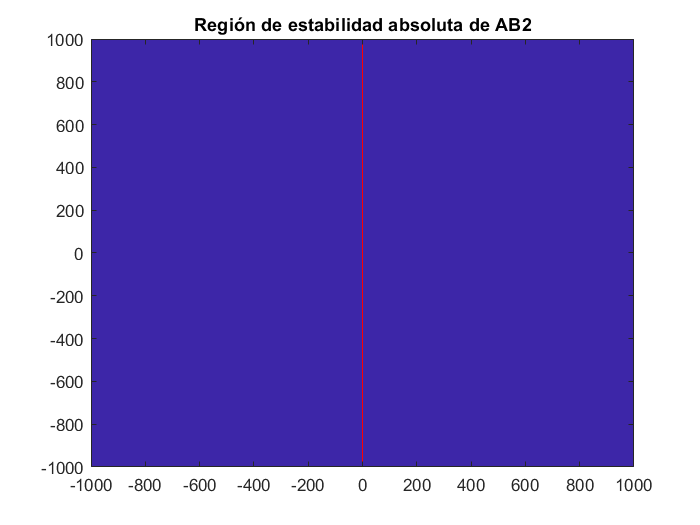

% Dibujo de la región de estabilidad
[X,Y] = meshgrid(-1000:1:1000,-1000:1:1000);
% Numeros complejos de la malla
Z = X+i*Y;
%una vez resuelto, escribimos las dos raices
u1 = @(z) [(3*sqrt(8*z/9+4/3)-4)/2*(2*z-1)];
u2 = @(z) [(-3*sqrt(8*z/9 + 4/3)+4)/ 2*(2*z-1)];

u1mat = u1(Z);
u2mat = u2(Z);
%nos queda que la region de estabilidad absoluta es la unión cuando se
%cumplen las condiciones de ambos valores menores o iguales que 1:
u1hat = 1 - abs(u1mat);
u2hat = 1 - abs(u2mat);
uhat = u1hat .* u2hat;

contourf(X,Y,uhat,[0,0])
hold on
plot([0,0],[-1000,1000],'r')
hold off
title('Región de estabilidad absoluta de DDF2')


%Como por mucho que ampliemos la región, nos sale que la estabilidad
%absoluta se cumple siempre, concluimos que o nos hemos equivocado en los
%calculos o la región de estabilidad es R^2 (lo cual no tiene muy buena
%pinta).

b) Elegir $h$ tal que el método aplicado a la ecuación $u' = -200 u$ satisfaga $U_n \to 0$ cuando $n \to \infty$, e aplicar el método para esta ecuación, inicializándolo mediante RK4. 

f=@(u,t)[-200u];

%RK4 para inicializar
function [t,U]=RK4(f,t_interv,u_0,N)
  t_0 = t_interv(1);
  T = t_interv(2);
  h = (T - t_0) / N;
  U = zeros(N,1);
  U(1) = u_0;
  t = zeros(N,1);
  t(1) = t_0;
  for i = 1 : (N-1)
      F1 = f(t(i), U(i));
      F2 = f(t(i) + (h/2), U(i) + h * (F1 / 2));
      F3 = f(t(i) + (h/2), U(i) + h *(F2 / 2));
      F4 = f(t(i) + h, U(i) + h * F3);
      
      U(i+1) = U(i) + (h/6) * (F1 + 2 * F2 + 2 * F3 + F4);
      t(i+1) = t(i) + h;
  end
end